clear
close all
addpath("..\data\geojsonR01\")
addpath("..\data\matlabMobile\")

% センサーデータの読み込みとまとめ
load("himeji2shinosaka.mat")

sensor = synchronize(Acceleration,AngularVelocity,MagneticField,Orientation,Position,'union','previous');
sensor = rmmissing(sensor);
% 時間を初期値を0にする
sensor.Timestamp = sensor.Timestamp-sensor.Timestamp(1);

%センサーの時間切り出し
sensor = sensor(1:100000,:)

sensor = 100000×18 timetable
    Timestamp    X_Acceleration    Y_Acceleration    Z_Acceleration    X_AngularVelocity    Y_AngularVelocity    Z_AngularVelocity    X_MagneticField    Y_MagneticField    Z_MagneticField    X_Orientation    Y_Orientation    Z_Orientation    latitude    longitude    altitude    speed    course    hacc
    _________    ______________    ______________    ______________    _________________    _________________    _________________    _______________    _______________    _______________    _____________    _____________    _____________    ________    _________    ________    _____    ______    ____

    00:00:00        -0.13966          -0.10703           9.6308             0.00216             0.001051             -0.003185            -34.227            -17.518            -18.071           113.82          -0.19071         -0.26199        34.827      134.69       18.871       0      258.4      10 
    00:00:00        -0.13966          -0.10703           9.63

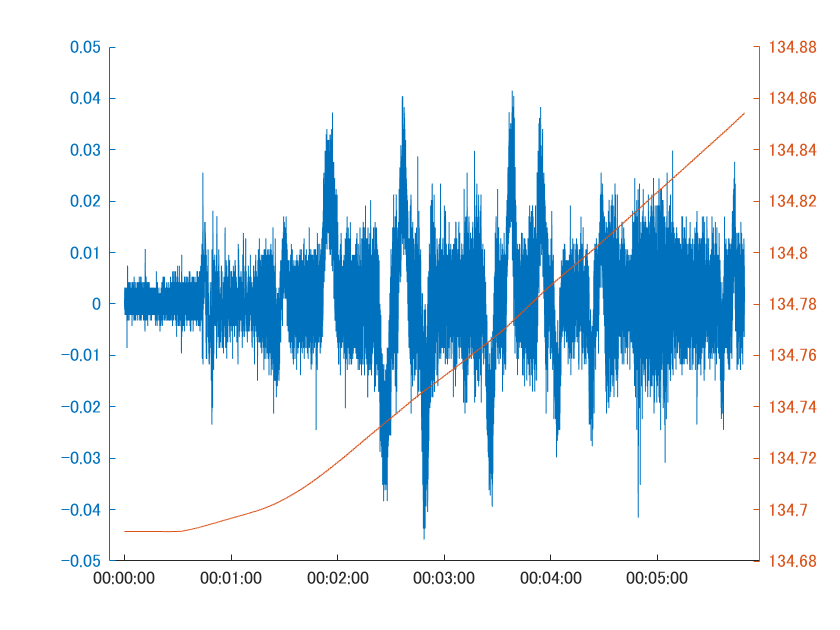

figure
hold on
yyaxis left
plot(sensor.Timestamp,sensor.Y_AngularVelocity)
yyaxis right
plot(sensor.Timestamp,sensor.longitude)
hold off

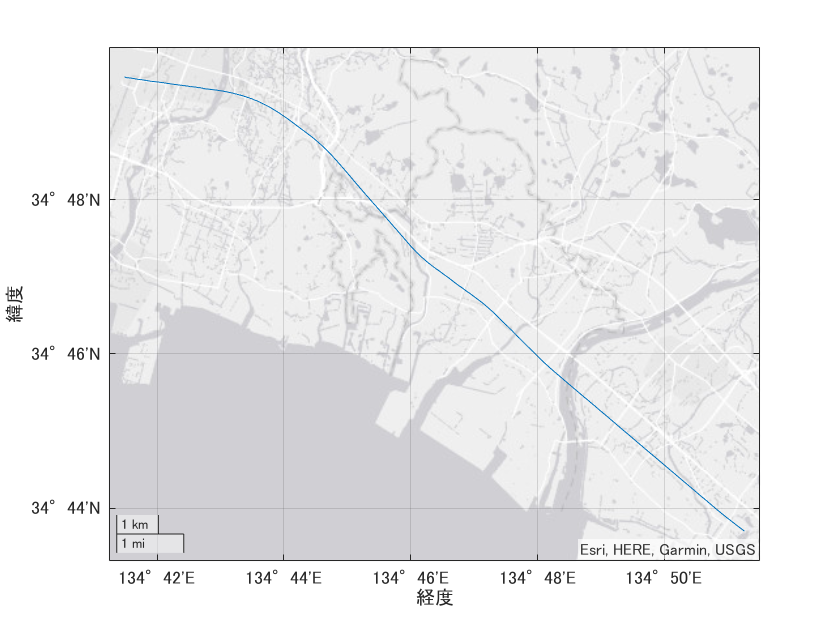

figure
geoplot(sensor.latitude,sensor.longitude)

dt = seconds(sensor.Timestamp(2:end)-sensor.Timestamp(1:end-1))

dt =     0.0040
    0.0030
    0.0030
    0.0040
    0.0030
    0.0030
    0.0040
    0.0030
    0.0030
    0.0040


vel = zeros(length(sensor.Timestamp),1);
for ii = 2:length(dt)+1
    vel(ii) = -sensor.Y_Acceleration(ii) * dt(ii-1) + vel(ii-1);
end
vel = detrend(vel)

vel =   -24.6858
  -24.6863
  -24.6871
  -24.6878
  -24.6884
  -24.6891
  -24.6898
  -24.6904
  -24.6911
  -24.6918


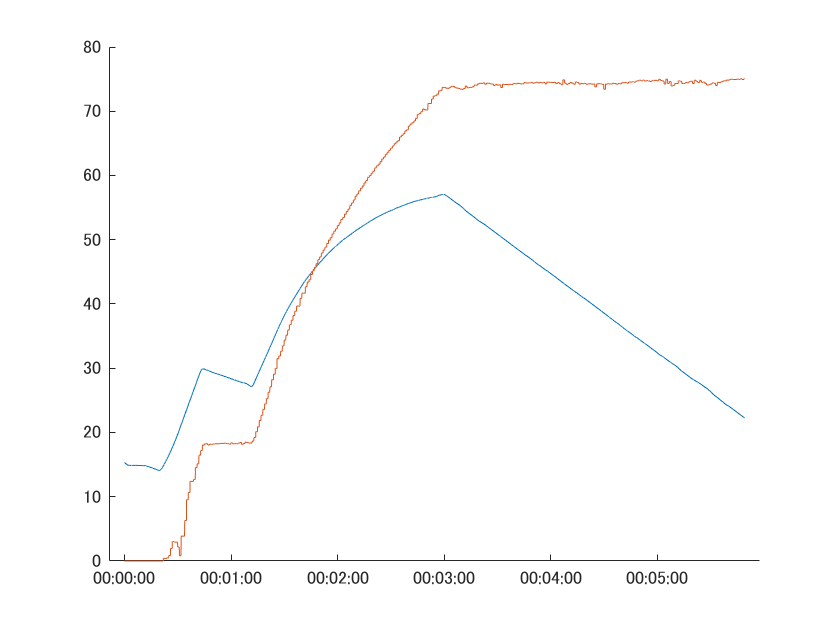

vel = vel + 40;
figure
hold on
plot(sensor.Timestamp,vel)
plot(sensor.Timestamp,sensor.speed)
hold off

%%　角度についてのデータ
windowsize = 1000;
% バイアスの確認
X_AngVelBias = mean(sensor.X_AngularVelocity(1:200,1))

X_AngVelBias = 0.0016

Y_AngVelBias = mean(sensor.Y_AngularVelocity(1:200,1))

Y_AngVelBias = 7.6436e-04

Z_AngVelBias = mean(sensor.Z_AngularVelocity(1:200,1))

Z_AngVelBias = -0.0047

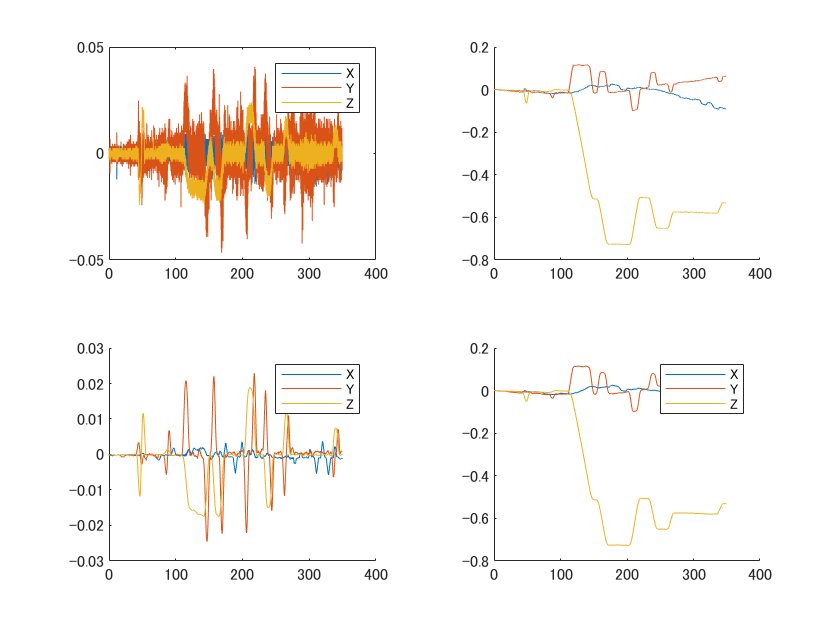


% 角度の修正
secondsTime = seconds(sensor.Timestamp);
X_AngVel = sensor.X_AngularVelocity-X_AngVelBias;
Y_AngVel = sensor.Y_AngularVelocity-Y_AngVelBias;
Z_AngVel = sensor.Z_AngularVelocity-Z_AngVelBias;


figure
tiledlayout(2,2);
nexttile;
AngVel = [X_AngVel,Y_AngVel,Z_AngVel];
plot(secondsTime,AngVel)
legend(["X","Y","Z"])

%角度変化
nexttile
Ang = cumtrapz(secondsTime,[X_AngVel,Y_AngVel,Z_AngVel],1);
% 下の方法と同義
% X_Ang = cumtrapz(secondsTime,X_AngVel)
% Y_Ang = cumtrapz(secondsTime,Y_AngVel)
% Z_Ang = cumtrapz(secondsTime,Z_AngVel)
hold on
plot(secondsTime,Ang(:,1))
plot(secondsTime,Ang(:,2))
plot(secondsTime,Ang(:,3))
hold off

%移動平均の移動プロット
nexttile;
hold on
plot(secondsTime,movmean(X_AngVel,windowsize))
plot(secondsTime,movmean(Y_AngVel,windowsize))
plot(secondsTime,movmean(Z_AngVel,windowsize))
legend(["X","Y","Z"])
hold off

nexttile;
hold on
plot(secondsTime,cumtrapz(secondsTime,movmean(X_AngVel,windowsize)))
plot(secondsTime,cumtrapz(secondsTime,movmean(Y_AngVel,windowsize)))
plot(secondsTime,cumtrapz(secondsTime,movmean(Z_AngVel,windowsize)))
legend(["X","Y","Z"])
hold off